clear all;
close all;
clc;

## NOTES:

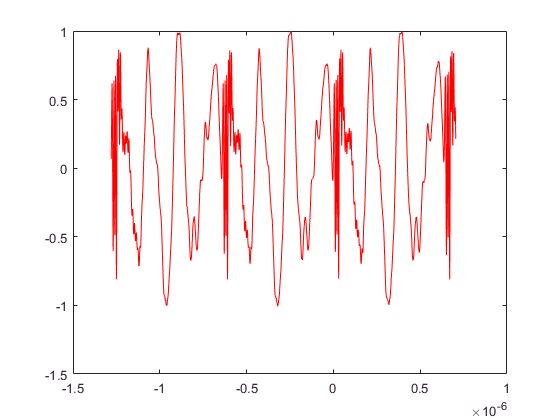

%(1)After inserting a new csv file, check which 
%%coulomn represents the echo and the reference signals.

%(2)plot the csv file and extract the start time of the first sawtooth signal,
%%then get the corresponding row number from the csv file, then update the
%%variable (start) with the new row number.

%(3)check the number of points in the csv file and update the variable
%(number_of _points) with this value.

T11=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\#Measurements 14-12-2017\last measurements\3m.csv',15,0,[15 0 2000 1]);
% T1=csvread('N:\T0022CH1.csv',17,0,[17 0 124999 2]);

T22=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\#Measurements 14-12-2017\last measurements\6m.csv',14,0,[14 0 2000 1]);
T33=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\#Measurements 14-12-2017\last measurements\9m.csv',15,0,[15 0 2000 1]);
T44=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\#Measurements 14-12-2017\last measurements\15m wall 200M BW.csv',15,0,[15 0 2000 1]);

 
 
plot(T11(:,1),T11(:,2)/max(T11(:,2)),'r');

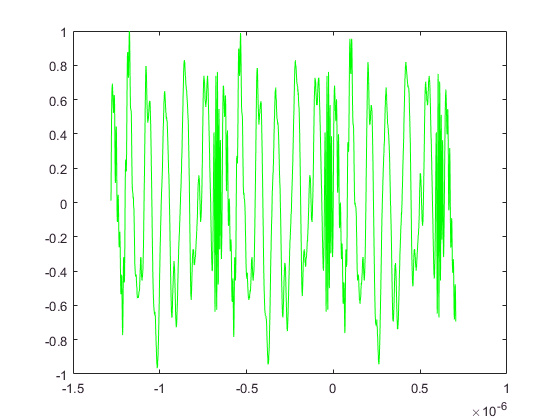

figure;
plot(T22(:,1),T22(:,2)/max(T22(:,2)),'g');

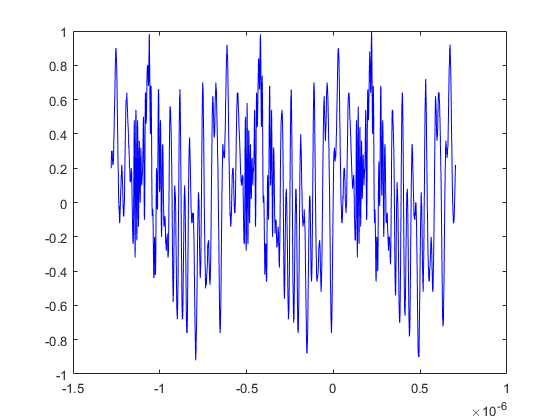

figure;
plot(T33(:,1),T33(:,2)/max(T33(:,2)),'b');

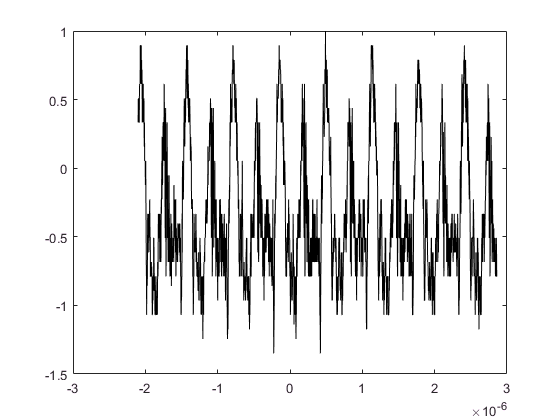

figure;
plot(T44(:,1),T44(:,2)/max(T44(:,2)),'k');

figure;
% figure;
% plot(T1(:,1),T1(:,3)/max(T1(:,3)));
% title('PLOT')
% figure;

## converting csv file into a matrix

q=T11(1,1);
qq=T11(2,1);
qqq=q-qq;
sampling_Rate=abs(1/qqq);
fs=sampling_Rate;
% SR=round(samplingRate);
LFM_Duration = 640e-9;
% number_of_points=length(T11(:,2));
number_of_points=length(T11(:,2));
p=number_of_points;
start=50;%63  58
IF_BW=100e6;
Detection_Range = (3e8)*LFM_Duration/2; 
Range_Resolution=(3e8)/(2*sampling_Rate);
Period1=round(Detection_Range/Range_Resolution); 

Period=round(sampling_Rate*LFM_Duration);
freq_per_pin=IF_BW/Period;
stop=start+Period-1;

for i=1:Period:p-2*Period
T1=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\#Measurements 14-12-2017\last measurements\2m 200M BW.csv',start+i,0,[start+i 0 500+i 1]);
T2=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\#Measurements 14-12-2017\last measurements\4m 200M BW.csv',start+i,0,[start+i 0 500+i 1]);
T3=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\#Measurements 14-12-2017\last measurements\6m 200M BW.csv',start+i,0,[start+i 0 500+i 1]);
T4=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\#Measurements 14-12-2017\last measurements\15m wall 200M BW.csv',start+i,0,[start+i 0 500+i 1]);

% T=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\measurement 06-07-2017\tek0000CH2.csv',start+i,0,[start+i 0 stop+i 2]);

% T=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\MEASUREMENT20-06-2017\Sheet_1m\tek0000ALL.csv',start+i,0,[start+i 0 stop+i 2]);

% T=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\mesurements 22-06-2017 2mixers\No target\tek0000ALL.csv',start+i,0,[start+i 0 stop+i 2]);


if i==1
    j=1;
else
    j=round(i/Period)+1;
end    
 Matrx1(j,:) = T1(:,2); %#ok<*SAGROW>
 Matrx2(j,:) = T2(:,2); %#ok<*SAGROW>
 Matrx3(j,:) = T3(:,2); %#ok<*SAGROW>
 Matrx4(j,:) = T4(:,2); %#ok<*SAGROW>
%  Reference_Matrix(j,:) = T(:,2);
%  zz=xcorr(Matrx(j,:),Reference_Matrix(j,:));
%  plot(Matrx1,'r');
%  hold on;
%  plot(Matrx2,'g');
%  hold on;
%  plot(Matrx3,'b');
%  hold on;
%  plot(Matrx4,'k');
%  hold on;
%  figure;
 
 
% plot(T(:,1),T(:,2),'r');
% title(['scan no: ',num2str(j)])
% figure;
% plot(T(:,1),T(:,3),'r');
% title(['scan no: ',num2str(j)])
% figure;
end

## Extracting Range

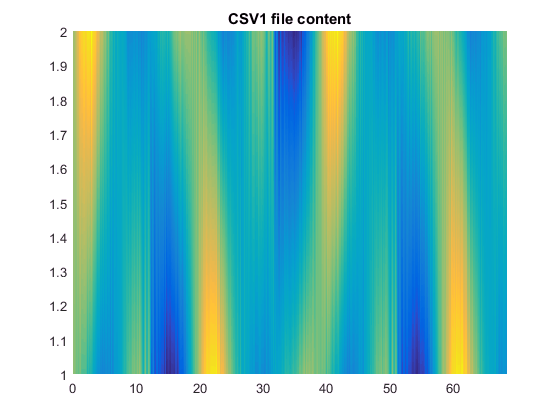

[m,n]=size(Matrx1);
% Tbin = abs(qqq);  % ns
Tbin=650e-9/Period;
T0 = 0; % ns
% c = 0.29979;  % m/ns
c=300000000;
range = c*(Tbin*(0:n-1) - T0)/2;  % Range Bins in meters
pcolor(range,1:j,transpose(Matrx1).'), shading interp;title('CSV1 file content')

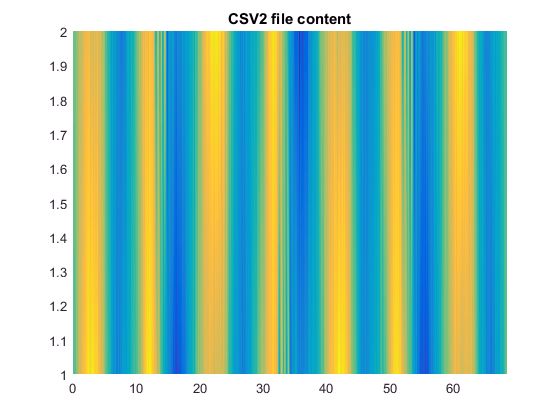

figure;
pcolor(range,1:j,transpose(Matrx2).'), shading interp;title('CSV2 file content')

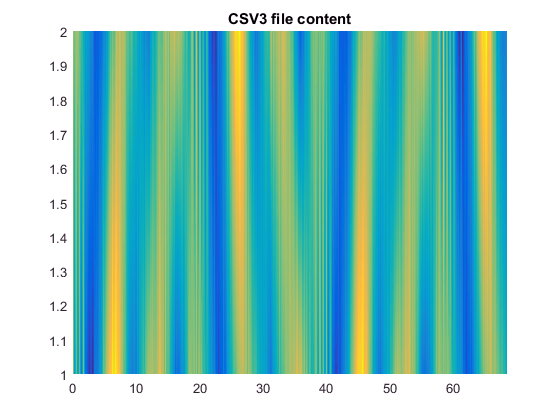

figure;
pcolor(range,1:j,transpose(Matrx3).'), shading interp;title('CSV3 file content')

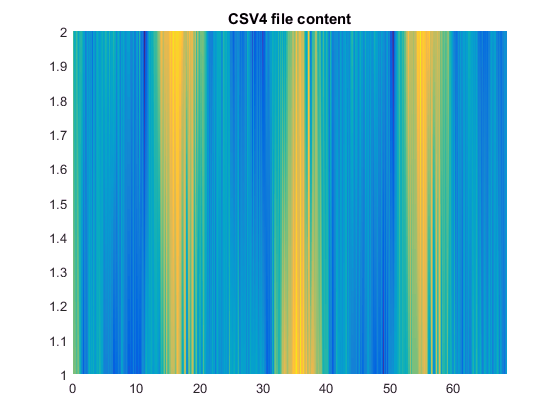

figure;
pcolor(range,1:j,transpose(Matrx4).'), shading interp;title('CSV4 file content')

figure;

%colormap(hot)

## FFT1

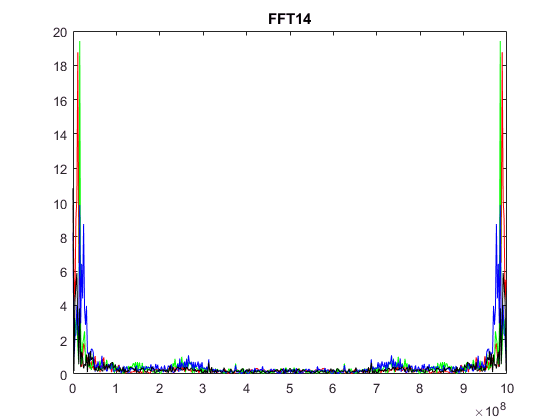

fs=sampling_Rate;
% fs=IF_BW
A1=fft((transpose(Matrx1)));
A2=fft(transpose(Matrx2));
A3=fft(transpose(Matrx3));
A4=fft(transpose(Matrx4));

B1=abs(A1);
B2=abs(A2);
B3=abs(A3);
B4=abs(A4);
fre=0:fs/n:fs-(fs/n);
% figure;

plot(fre,B1(:,2),'r'), shading interp;title('FFT11'); hold on;
plot(fre,B2(:,2),'g'), shading interp;title('FFT12'); hold on;
plot(fre,B3(:,2),'b'), shading interp;title('FFT13'); hold on;
plot(fre,B4(:,2),'k'), shading interp;title('FFT14'); hold on;

% pcolor(fre,1:(m),transpose(B)), shading interp;
% colormap(hot)

## FFT2

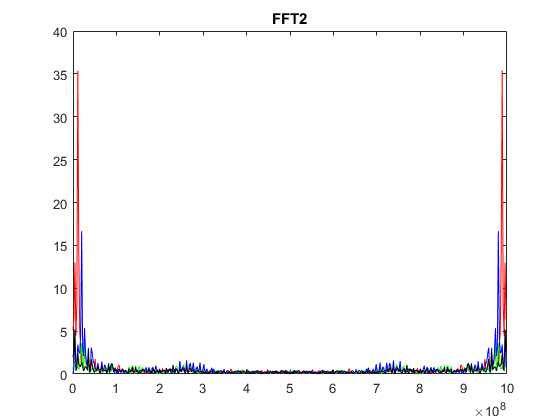

fs=sampling_Rate;
% fs=IF_BW
C1=fft(transpose(A1));
C2=fft(transpose(A2));
C3=fft(transpose(A3));
C4=fft(transpose(A4));

DD1=abs(C1);
DD2=abs(C2);
DD3=abs(C3);
DD4=abs(C4);

fre=0:fs/n:fs-(fs/n);
figure; 
plot(fre,DD1(2,:),'r'), shading interp;hold on; 
plot(fre,DD2(2,:),'g'), shading interp;hold on; 
plot(fre,DD3(2,:),'b'), shading interp;hold on; 
plot(fre,DD4(2,:),'k'), shading interp;hold on;
%colormap(hot)
title('FFT2')

## FFT3

 fs=sampling_Rate;
% fs=IF_BW
 C=fft((Matrx1))

C =     0.1006    0.0754    0.0930    0.0955    0.1006    0.1232    0.1156    0.1558    0.1558    0.1483    0.1483    0.1609    0.1609    0.1483    0.1483    0.1357    0.1483    0.1357    0.1282    0.1558    0.1282    0.0955    0.0880    0.0754    0.0478    0.0202    0.0076    0.0202   -0.0251   -0.0452   -0.0200   -0.0527   -0.0527   -0.0728   -0.0527   -0.0803   -0.0929   -0.0728   -0.1055   -0.1306   -0.1004   -0.1281   -0.1406   -0.1055   -0.1256   -0.1331   -0.1130   -0.1130   -0.1180   -0.1130
   -0.0126   -0.0126   -0.0201   -0.0477   -0.0678   -0.0754   -0.0930   -0.1080   -0.1080   -0.1407   -0.1407   -0.1533   -0.1533   -0.1407   -0.1558   -0.1935   -0.1809   -0.1935   -0.1759   -0.2136   -0.2010   -0.2085   -0.2010   -0.2136   -0.2010   -0.1884   -0.2010   -0.1884   -0.1683   -0.1734   -0.1734   -0.1809   -0.1407   -0.1457   -0.1407   -0.1131   -0.1156   -0.1206   -0.0879   -0.0879   -0.0678   -0.0804   -0.0528   -0.0477   -0.0276   -0.0201   -0.0402   -0.0251   -0.0201     

 D=abs(C);
 fre=0:fs/n:fs-(fs/n)

fre =    1.0e+08 *

         0    0.0222    0.0443    0.0665    0.0887    0.1109    0.1330    0.1552    0.1774    0.1996    0.2217    0.2439    0.2661    0.2882    0.3104    0.3326    0.3548    0.3769    0.3991    0.4213    0.4435    0.4656    0.4878    0.5100    0.5322    0.5543    0.5765    0.5987    0.6208    0.6430    0.6652    0.6874    0.7095    0.7317    0.7539    0.7761    0.7982    0.8204    0.8426    0.8647    0.8869    0.9091    0.9313    0.9534    0.9756    0.9978    1.0200    1.0421    1.0643    1.0865


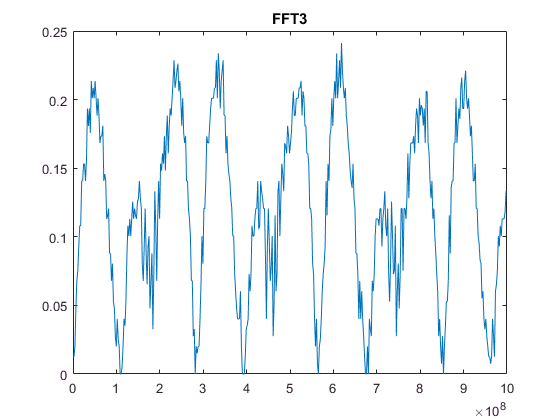

 figure;
 plot(fre,D(2,:)), shading interp;
 %colormap(hot)
 title('FFT3')

## FFT4

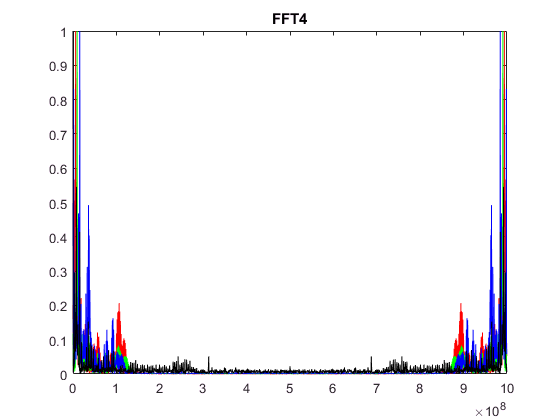

fs=sampling_Rate;
% fs=IF_BW
E1=fft(T11(1:1986,2));
E2=fft(T22(1:1986,2));
E3=fft(T33(1:1986,2));
E4=fft(T44(1:1986,2));


for i=1:length(E1)
   
    if abs(real(E1(i))) >=abs( imag(E1(i)))
        F1(i)= abs((real(E1(i))/2)) + abs(imag(E1(i)));
    else
        F1(i)= abs((real(E1(i)))) + abs((imag(E1(i))/2));
    end
end;    


% F1=abs(E1);
% F2=abs(E2);
% F3=abs(E3);
% F4=abs(E4);

F1=F1/max(F1);
% F1=abs(abs(E1)/(max(abs(E1))));
F2=abs(abs(E2)/(max(abs(E2))));
F3=abs(abs(E3)/(max(abs(E3))));
F4=abs(abs(E4)/(max(abs(E4))));
% fre=0:fs/(2*p):(fs/2)-(fs/(2*p)); %% half band
fre=0:fs/(p):(fs)-(fs/(p));
fre1=0:fs/p:fs-2*(fs/p);
figure;

plot(fre,(F1(1:p)),'r');hold on;
plot(fre,(F2(1:p)),'g');hold on;
plot(fre,(F3(1:p)),'b');hold on;
plot(fre,(F4(1:p)),'k');hold on;


title('FFT4')

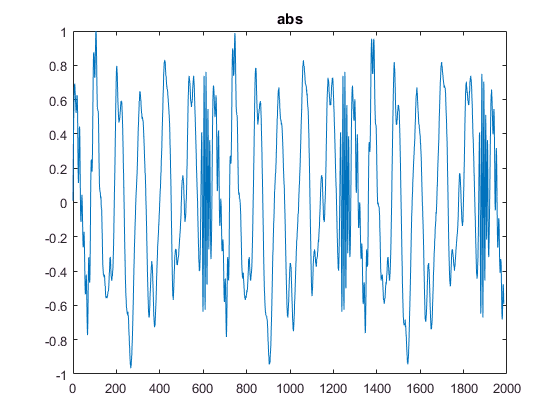


L=p;
y1=((T22(1:1986,2))/(max(abs(T22(1:1986,2)))));
figure;
plot((0:1:L-1),y1)
title('abs')

## Generating COE file

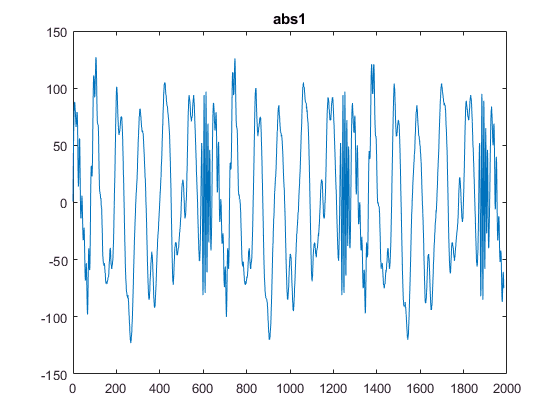

yy=(round(127*y1));
zzz=max(yy);
figure;
plot((0:1:L-1),yy)
title('abs1')

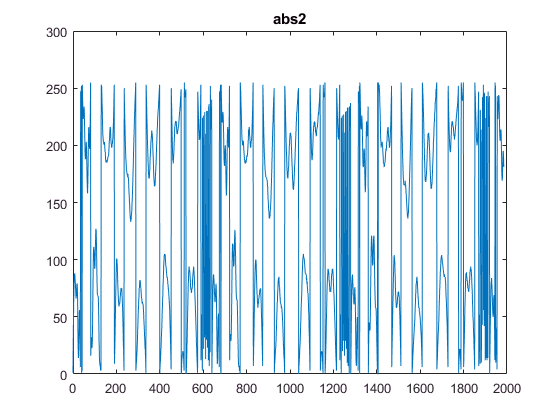

for u = 1: length(yy)
    if yy(u)<0
        yy(u)=yy(u)+256;
    end    
end
% for u = 1: length(yy)
%     if yy(u)<0;
%         yy(u)=0;
%     end     
% % end
% % 
romdata=dec2bin(yy,8);
figure;
plot((0:1:L-1),yy)
title('abs2')

% ROM data 
    aaa1=[]

aaa1 = []

%     x=round(x);
%     s_bin1=dec2bin(x,12);
     aaa=[aaa1;romdata]

aaa = 00000001
00010111
00101011
00111101
01000111
01010001
01010101
01010111
01011000
01010101
01010001
01001111
01001010
01000111
01000010
01000100
01000101
01001010
01001111
01001111
01001100
01000100
00110100
00100000
00010100
00001110
00010001
00011101
00101000
00110111
00111000
00110111
00101000
00010111
00000110
11110111
11110011
11110010
11110111
11111100
00000001
00000110
00000011
11111101
11110011
11101010
11100010
11011111
11100000
11100101
11100111
11101010
11100101
11011101
11010010
11001000
10111111
10111100
10111100
11000010
11000101
11001011
11001000
10111111
10110101
10101001
10100010
10011110
10100100
10101111
10111111
11001100
11010110
11011000
11010010
11001011
11000101
11000101
11001001
11010110
11100111
11111111
00010000
00011001
00100000
00100000
00011010
00010111
00010111
00011101
00101000
00111011
01001100
01011100
01101001
01101111
01101111
01101100
01101000
01100001
01011100
01011110
01100101
01101110
01110101
01111110
01111111
01111100
01110011
01101000
0101

%       end
%*******************storing real data in real.txt**********************************************    
fid1 = fopen('4m.coe','w');
fprintf(fid1,'MEMORY_INITIALIZATION_RADIX=2;\n');
fprintf(fid1,'MEMORY_INITIALIZATION_VECTOR=');
 
for a1=1:L
    fprintf(fid1,aaa(a1,:));
    if a1==L
        fprintf(fid1,';');
    else
        fprintf(fid1,',');
    end
end




fclose(fid1);



## applying MTI filter

% for i=1:j-1
% MatrxMTI(i,:)=Matrx1(i,:) - Matrx1(i+1,:);
% end
% pcolor(range,1:j-1,transpose(MatrxMTI).'), shading interp;
% %colormap(hot)
% title('After MTI')
% figure;

## Applying SVD

% [U, S, V]=svd(Matrx1);
%  S(1,1)=0;
% z1=U*S*V;
% pcolor(range,1:j,transpose(z1).'), shading interp;
% %colormap(hot)
% title('SVD')

## Pull out the raw scans (if saved)

% rawscansI = 1:Period;
% rawscansV =reshape(Matrx,[],Period)';%array of no of scans horizontal and range vertical
% [m,n]=size(Matrx);
% % Tbin = abs(qqq);  % ns
% Tbin=650e-9/Period;
% T0 = 0; % ns
% % c = 0.29979;  % m/ns
% c=300000000;
% range = c*(Tbin*(0:n-1) - T0)/2;  % Range Bins in meters
% figure;
% pcolor(range,1:j,rawscansV.'), shading interp;
% colormap(hot)
% xlabel('range (m)');
% ylabel('scan number)');
% title('CSV file content old method')

## Variance

% M=var(transpose(Matrx));
% M=var((Matrx1));
% figure;
% plot(range,M);
% xlabel('range (m)');
% ylabel('scan number)');
% title('Variance')

## FFT1

% A=fft(transpose(Matrx));
% B=real(A);
% freq_range = (freq_per_pin*(0:n-1) - 0); %
% freq_Hz = (sampling_Rate*[0:n-1]/n);     % same as freq
% % n_2=ciel(n/2);
% figure;
% pcolor(freq_Hz,1:m,transpose(B)), shading interp;
% colormap(hot)
% title('FFT1')
% figure;
% plot(freq_range,B(:,2))
% title('FFT1')

## FFT with MTI

% A=fft(transpose(MatrxMTI));
% B=real(A);
% freq_range = (freq_per_pin*(0:n-1) - 0); %
% freq_Hz = (sampling_Rate*[0:n-1]/n);     % same as freq
% % n_2=ciel(n/2);
% figure;
% pcolor(freq_Hz,1:m-1,transpose(B)), shading interp;
% colormap(hot)
% title('FFT with MTI')
% figure;
% plot(freq_Hz,B(:,2))
% title('FFT with MTI')



%%old

% 
% T1=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\Measurements 09-07-2017\9-7-2017\no_target.csv',15,0,[15 0 10000 2]);
% 
% % T1=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\MEASUREMENT20-06-2017\Sheet_3m\tek0000ALL.csv',14,0,[14 0 10014 2]);
% % T1=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\mesurements 22-06-2017 2mixers\No target\tek0000ALL.csv',15,0,[15 0 10014 2]);
% 
% plot(T1(:,1),T1(:,2)/max(T1(:,2)),'r');
% hold on;
% % figure;
% plot(T1(:,1),T1(:,3)/max(T1(:,3)));
% title('PLOT')
% figure;
% %%
% %%
% %% converting csv file into a matrix
% %%
% q=T1(1,1);
% qq=T1(2,1);
% qqq=q-qq;
% sampling_Rate=abs(1/qqq);
% % SR=round(samplingRate);
% LFM_Duration = 640e-9;
% number_of_points=length(T1(:,2)); 
% p=number_of_points;
% start=1160;%63  58
% IF_BW=500e6;
% Detection_Range = (3e8)*LFM_Duration/2; 
% Range_Resolution=(3e8)/(2*sampling_Rate);
% Period1=round(Detection_Range/Range_Resolution); 
% 
% Period=round(sampling_Rate*LFM_Duration);
% freq_per_pin=IF_BW/Period;
% stop=start+Period-1;
% 
% for i=1:Period:p-2*Period
% T=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\Measurements 09-07-2017\9-7-2017\no_target.csv',start+i,0,[start+i 0 stop+i 2]);
% % T=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\measurement 06-07-2017\tek0000CH2.csv',start+i,0,[start+i 0 stop+i 2]);
% 
% % T=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\MEASUREMENT20-06-2017\Sheet_1m\tek0000ALL.csv',start+i,0,[start+i 0 stop+i 2]);
% 
% % T=csvread('D:\1XlinxRADAR19102016\Masters\Dr.Mabrouk\mesurements 22-06-2017 2mixers\No target\tek0000ALL.csv',start+i,0,[start+i 0 stop+i 2]);
% 
% 
% if i==1
%     j=1;
% else
%     j=round(i/Period)+1;
% end    
%  Matrx(j,:) = T(:,3); %#ok<*SAGROW>
%  Reference_Matrix(j,:) = T(:,2);
%  zz=xcorr(Matrx(j,:),Reference_Matrix(j,:));
%  plot(zz,'k');
%  hold on;
%  
% % plot(T(:,1),T(:,2),'r');
% % title(['scan no: ',num2str(j)])
% % figure;
% % plot(T(:,1),T(:,3),'r');
% % title(['scan no: ',num2str(j)])
% % figure;
% end
% 
% 












% %% using BPF applied for every range bin
% nn1=8; % filter order
% fs1=200E6;%sampling frequency
% s11=(4E9)/fs1;%normalized pass frequency
% s21=(6E9)/fs1;%normalized stop frequency
% [b11,a11] = butter(nn1,[s11 s21],'bandpass');%first bandpass butter worth filter from 3.1-5.1 GHz
% y=zeros(m,n);
% 
% for i=1:n
%   y(:,i) = filter(b11,a11,j(:,i));
% end
% %%%%%%%%%%%%%%%%%%%%
% q3=var(transpose(y));
% %%%%%%%%%%%%%%%%%%%%%
% %using MTI filter applied for all scans in every range bins
% filter1=zeros(m,n-1000);
% a=[1, -1];
% b=1;
% for i = 1:m
%   filter1(i,:) = filter(a,b,y(i,:));
% end
% %%%%%%%%%%%%%%%%%%%%
% q4=var(transpose(filter1));
% %%%%%%%%%%%%%%%%%%%%
% %using BPF applied for every scan in all range bins (human breathing rate
% %0.1~1 Hz.
% nn=3;
% fs=50;
% s1=(0.2)/fs;%normalized pass frequency
% s2=(2)/fs;%normalized pass frequency0
% [b1,a1] = butter(nn,[s1 s2],'bandpass');%escond bandpass butter worth filter from 0.3-0.8 hz
% y5=zeros(m,n-1000);
% %% with MTI
% for i=1:m
%   y5(i,:) = filter(b1,a1,filter1(i,:));
% end
% %%%%%%%%%%%%%%%%%%%%%
% q5=var(transpose(y5));
% %%%%%%%%%%%%%%%%%%%%%
% figure;
% pcolor(range,1:n-1000,y5.'), shading interp;
% colormap(hot)
% xlabel('range (m)');
% ylabel('scan number');title('after BPF with 2nd MTI');









% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% % figure;
% % plot(F(:,1),F(:,2));    %/max(F(:,2))
% % xlabel('Frequency (Hz)');
% % ylabel('Amplitude (Volt)');grid;
% 
% 
% 
% % 
% % 
% % % hold on;
% % % plot(t(:,1),t(:,3)/max(t(:,3)),'r');
% % % xlabel('time (seconds)');
% % % ylabel('amplitude (Volts)');grid;
% % 
% % figure;
% % plot(t(:,2)/max(t(:,2)));
% % xlabel('time (seconds)');
% % ylabel('amplitude (Volts)');grid;
% % 
% % % hold on;
% % % plot(t(:,3)/max(t(:,3)),'r');
% % % xlabel('time (seconds)');
% % % ylabel('amplitude (Volts)');grid;
% % 
% % figure;
% % plot(t(121:323,1),t(121:323,2));
% % xlabel('aa');
% % 
% % 
% fs=200E6;
% x=T(:,2);
% x_ds=downsample(x,16);
% fs=12.5E6;
% y=fft(x_ds);
% k=length(x_ds);
% fre=0:fs/k:fs-(fs/k);
% fre1=0:fs/k:fs-2*(fs/k);
% %y(1)=0;
% figure;
% plot(fre,abs(y))
%  
% z=diff(x_ds);
% % for n=2:k
% %     z=x(n)-x(n-1);
% % end
% z1=fft(z);
% 
% figure;
% plot(fre1,abs(z1))
% % nn1=8; % filter order
% % s11=(0.004E6)/fs;%normalized pass frequency
% % s21=(4E6)/fs;%normalized stop frequency
% % [b11,a11] = butter(nn1,[s11 s21],'bandpass');%first bandpass butter worth filter from 3.1-5.1 GHz
% %   phi = filter(b11,a11,z);
% %   z2=fft(phi);
% % 
% %   figure;
% % plot(fre1,abs(z2))
% % xlabel('z2');
% %   phi1 = filter(b11,a11,x_ds);
% %   z3=fft(phi1);
% % 
% %   figure;
% % plot(fre,abs(z3))